# Vacchini Edoardo 467102

Partendo dai dati puliti si può ora partire con la fase di identificazione del modello. Questa verrà fatta considerando i seguenti modelli:

- **Modello cubico**: si tratta di un modello di riferimento del caso. Si spezza l'intervallo di dati in 3 e si identifica un modello cubico per l'intervallo tra la *cut-in wind speed* e la *cut-out wind speed*, ovvero dove non è presente la saturazione. 

- **Modello a doppio esponenziale**: prende in considerazione la curva fino alla cutout speed.

- **Funzione logistica**: grazie alla sua forma a sigmoide si potrebbe prestarsi bene

Per prima cosa preparo i dati di identificazione e quelli di validazione spezzando in due il dataset e imposto il dizionario per avere una struttura dati che contenga tutti gli indici per la validazione e scelta del modello.

clc; clear; close all;
turbines = readtable('clean_dataset.csv');

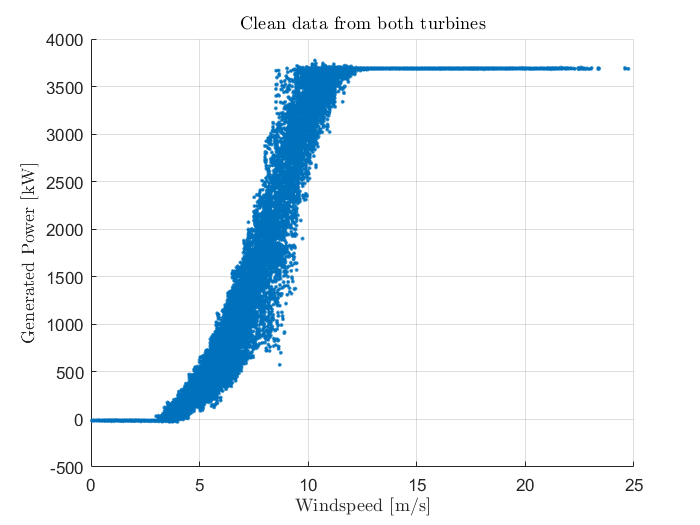

figure;
scatter(turbines.windspeed, turbines.power, '.');
grid on;
title('Clean data from both turbines', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

Spezzo il dataset in due set, uno di training e uno di validazione.

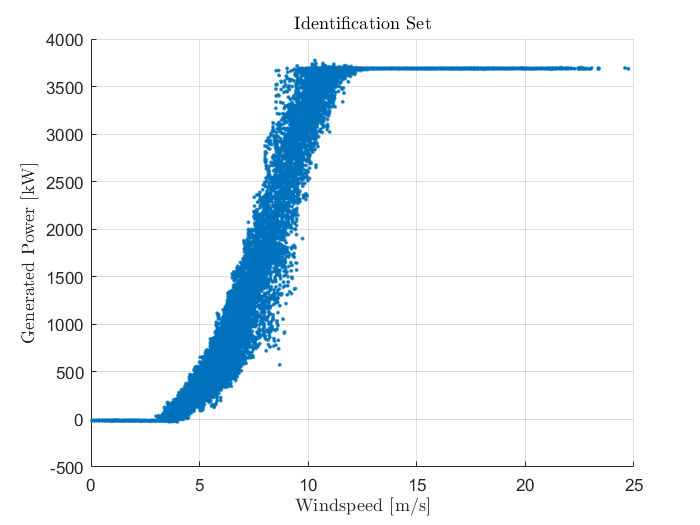

trainingPercentage = 0.8;

trainingSet = turbines(randperm(size(turbines, 1), floor(trainingPercentage * size(turbines, 1))), :);
validationSet = setdiff(turbines, trainingSet);

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
grid on;
title('Identification Set', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

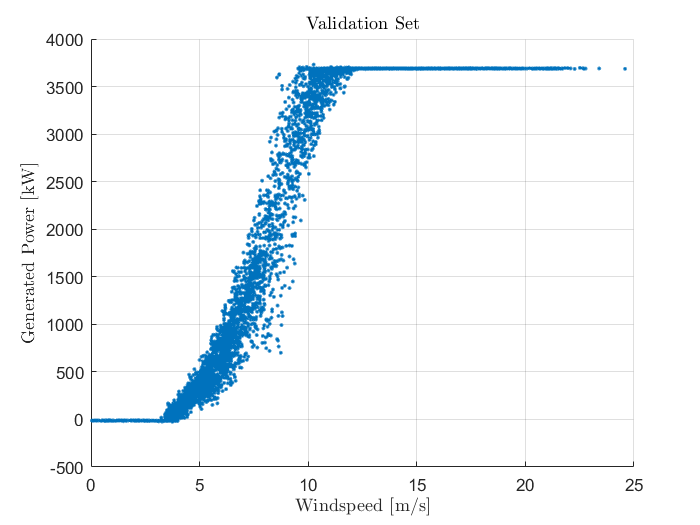

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
grid on;
title('Validation Set', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

### Modello Benchmark

Il modello benchmark è costuito da una semplice funzione cubica nell'intervallo incluso tra le velocità di *cut-in* e di *cut-out*.


$$P\left(v\right)=\frac{1}{2}\rho {\;}_{\textrm{air}} A\;v^{3\;}$$


Dove $\rho_{\textrm{air}}$ è la densità dell'aria e $A$ è l'area della spazzata, ovvero la superficie coperta dalla pala di raggio $r=65m$.

cutin_windspeed = 3;
cutout_windspeed = 12;

datainrange = trainingSet(trainingSet.windspeed >= cutin_windspeed & trainingSet.windspeed <= cutout_windspeed, :);
[theta, sigma] = lscov(datainrange.windspeed.^3, datainrange.power);
Y_Hat = datainrange.windspeed.^3 * theta;

Nella sezione di saturazione per completare il modello su tutto l'intervallo di velocità del vento, uso il valore medio delle saturazioni vere e lo applico da quando la curva cubica supera il livello di saturazione;

saturationValue = mean(trainingSet(trainingSet.windspeed > 12,:).power);

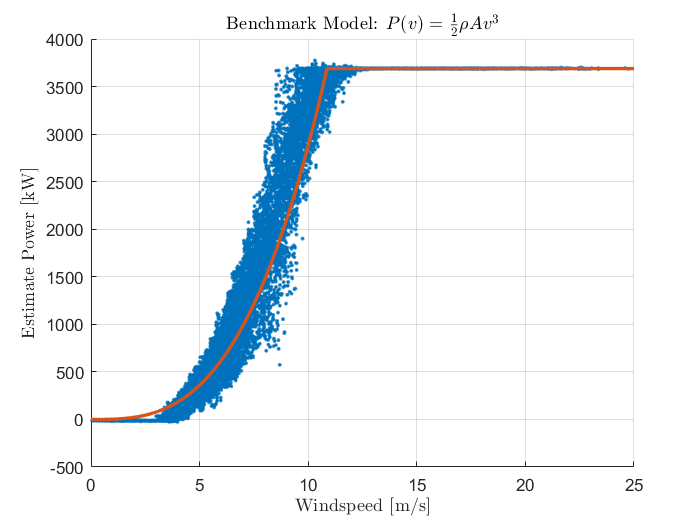

density = 0.01;
saturationWindspeed = 10.88;
windspeedGrid = [0 : density : saturationWindspeed - density]';
PHIGrid = windspeedGrid.^3;
windspeedGrid = [windspeedGrid; [10.88 : density : 25]'];

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
grid on;
plot(windspeedGrid, [PHIGrid * theta; saturationValue * ones(length(windspeedGrid) - length(PHIGrid),1)], "LineWidth", 2);
title('Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

benchmarkModel.parameters = theta;
benchmarkModel.standardDeviation = sigma;
benchmarkModel.MSE = (1/length(Y_Hat)) * sum((datainrange.power - Y_Hat).^2);
benchmarkModel.SSR = sum((datainrange.power - Y_Hat).^2);
benchmarkModel.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * benchmarkModel.SSR ;
benchmarkModel.AIC = (2*length(theta) / length(Y_Hat)) * log(sum((datainrange.power - Y_Hat).^2));
benchmarkModel.MDL = (log(length(Y_Hat))*length(theta) / length(Y_Hat)) * log(sum((datainrange.power - Y_Hat).^2));

### Modello cubico

Un modello di riferimento è quello cubico, con cui si modellizza il tratto crescente con un modello:


$$P\left(v\right)=\theta_1 +\theta_2 v+\theta_3 v^{2\;} +\theta_4 v^3$$


cutin_windspeed = 1;
cutout_windspeed = 12.5;

datainrange = trainingSet(trainingSet.windspeed < cutout_windspeed & trainingSet.windspeed > cutin_windspeed, :);

PHI = [ones(length(datainrange.windspeed), 1), datainrange.windspeed, datainrange.windspeed.^2, datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;


cubicModel_fourth.parameters = theta;
cubicModel_fourth.standardDeviation = sigma;
cubicModel_fourth.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_fourth.SSR = sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_fourth.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * cubicModel_fourth.SSR;
cubicModel_fourth.AIC = ((2*length(theta))/(length(Y_Hat)))*log(cubicModel_fourth.SSR);
cubicModel_fourth.MDL = ((log(length(Y_Hat))*length(theta)) / (length(Y_Hat))) * log(cubicModel_fourth.SSR);

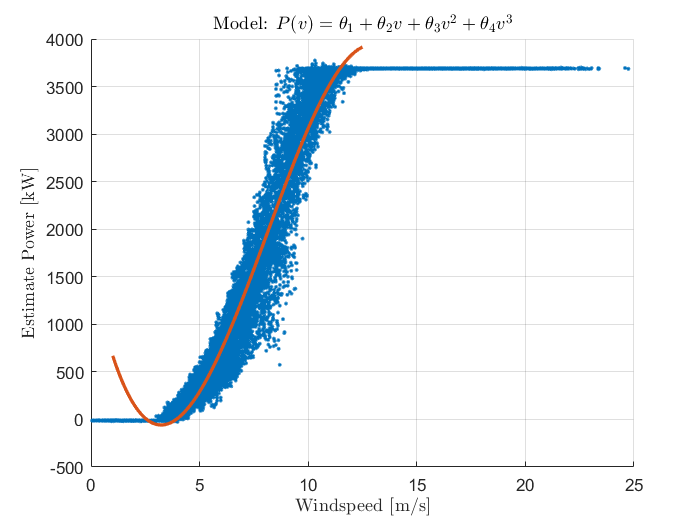

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [ones((cutout_windspeed - cutin_windspeed)/density + 1, 1), windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, PHIGrid * theta, "LineWidth", 2);
grid on;
title('Model: $P(v) = \theta_1 + \theta_2 v + \theta_3 v^2 + \theta_4 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

Prendo in considerazione modelli cubici di ordini diversi:


$$P\left(v\right)=\theta_1 v+\theta_2 v^{2\;} +\theta_3 v^3$$


PHI = [datainrange.windspeed, datainrange.windspeed.^2, datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;

cubicModel_third.parameters = theta;
cubicModel_third.standardDeviation = sigma;
cubicModel_third.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_third.SSR = sum((datainrange.windspeed - Y_Hat).^2);

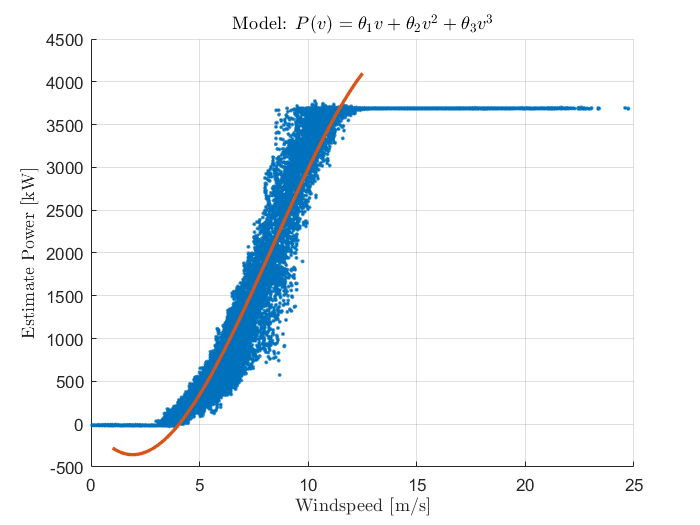

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];


figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, PHIGrid * theta, "LineWidth", 2);
grid on;
title('Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

Un modello cubico differente è quello che è ottenibile dal modello benchmark, traslato, quindi a cui si somma un termine costante.


$$P\left(v\right)=\theta_2 {\left(v-v_0 \right)}^3 =\;\theta_1 +\theta_2 v^3$$


PHI = [ones(length(datainrange.windspeed), 1), datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;

cubicModel_second.parameters = theta;
cubicModel_second.standardDeviation = sigma;
cubicModel_second.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_second.SSR = sum((datainrange.windspeed - Y_Hat).^2);

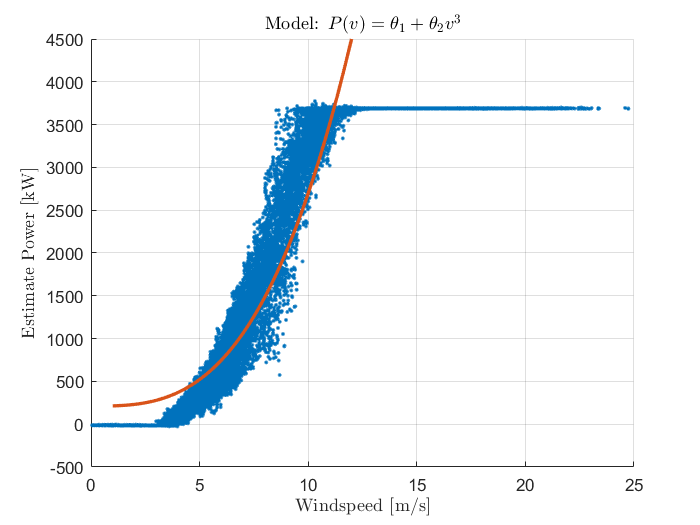

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [ones((cutout_windspeed - cutin_windspeed)/density + 1, 1), windspeedGrid.^3];

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, PHIGrid * theta, "LineWidth", 2);
grid on;
title('Model: $P(v) = \theta_1 + \theta_2 v^3$', 'Interpreter', 'latex');
axis([0,25, -500, 4500]);
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

## Modello a doppio esponenziale

Il secondo tipo di modello preso in consideraizone è quello a doppio esponenziale. Il doppio esponenziale ha la forma classica del sigmoide che presenta anche la curva di potenza classica. Il modello a doppio esponenziale è della forma:


$$P(v) = e^{-e^ {\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$$
  

Attraverso un estrazione di due logaritmi naturali è possibile ricondurre a un modello lineare nei parametri:


$$log(-log(P(v))) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$$


In questo caso l'intervallo di valori presi in considerazione è quello al di sotto della velocità di cut-out del vento. Necessario prendere solo i valori di potenza strettamente positivi a causa della presenza del logaritmo. Inoltre $P\left(v\right)$ deve essere la funzione normalizzata, ovvero con valori $P\left(v\right)\in \left\lbrack 0,1\right\rbrack$, siccome il meno logaritmo deve essere definito.

cutout_windspeed = 15;
cutin_windspeed = 3;

datainrange = trainingSet(trainingSet.power > 0 & trainingSet.windspeed < cutout_windspeed , :);
scale = max(datainrange.power);
logData = [datainrange.windspeed, log(-log(datainrange.power*(1/scale)))];

PHI = [logData(:,1), logData(:,1).^2, logData(:,1).^3];
[theta, sigma] = lscov(PHI, logData(:,2));
Y_Hat = scale * exp(-exp(PHI*theta));

doubleExponentialModel.parameters = theta;
doubleExponentialModel.standardDeviation = sigma;
doubleExponentialModel.MSE = (1/length(Y_Hat))*sum((datainrange.windspeed - Y_Hat).^2);
doubleExponentialModel.SSR = sum((datainrange.windspeed - Y_Hat).^2);

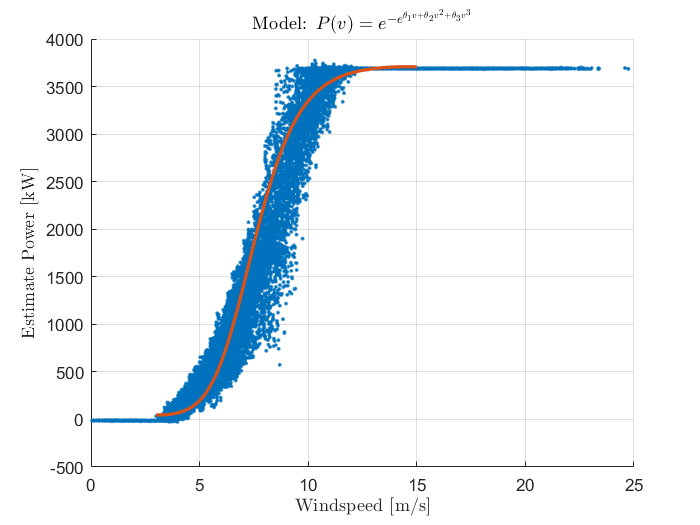

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, scale * exp(-exp(PHIGrid * theta)) ,"LineWidth", 2);
grid on;
title('Model: $P(v) = e^{-e^{\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');

## Funzione Logistica

La funzione logistica ha la caratteristica forma a sigmoide simile alla forma della curva di potenza da modellizzare:


$$P\left(v\right)=\frac{\theta_1 }{1+\theta_2 e^{-\theta_3 v} }$$


E' un modello non linrare, quindi va applicato un algoritmo iterativo come quello di Gauss-Newton con variante di Levenberg-Marquardt siccome le matrici appaiono singolari. (Non ho trovato un modo di aggiungerlo o specificarla, allora ho trovato un compromesso dato dal fatto che avevo una buona inizializzazione dal lavoro fatto dall'algoritmo di discesa del gradiente su Python).

theta_k = [3660.7829371863613, 68820 , 1.7373709296426687]';

iterations = 100;
normalization_factor = 1 / max(trainingSet.windspeed);
normalized_power = normalization_factor * trainingSet.power;
model_order = length(theta_k);

for i = 1:iterations
    [phi_1, phi_2, phi_3] = gradient_logistic(trainingSet.windspeed, theta_k);
    PHI_k = [phi_1, phi_2, phi_3];
    Y_tilde = normalized_power - normalization_factor * logistic(trainingSet.windspeed, theta_k);
    theta_tilde = inv( PHI_k' * PHI_k + (8 + i*5e-2)*1e-5 * eye(model_order) ) * (PHI_k' * Y_tilde);
    theta_k = theta_k + theta_tilde;
end

ans =     1.0000    0.3356   -0.2628
    0.3356    1.0000   -0.9929
   -0.2628   -0.9929    1.0000


ans =     1.0000    0.3526   -0.2744
    0.3526    1.0000   -0.9921
   -0.2744   -0.9921    1.0000


ans =     1.0000    0.3683   -0.2848
    0.3683    1.0000   -0.9913
   -0.2848   -0.9913    1.0000


ans =     1.0000    0.3825   -0.2937
    0.3825    1.0000   -0.9904
   -0.2937   -0.9904    1.0000


ans =     1.0000    0.3953   -0.3012
    0.3953    1.0000   -0.9895
   -0.3012   -0.9895    1.0000


ans =     1.0000    0.4068   -0.3073
    0.4068    1.0000   -0.9886
   -0.3073   -0.9886    1.0000


ans =     1.0000    0.4169   -0.3122
    0.4169    1.0000   -0.9876
   -0.3122   -0.9876    1.0000


ans =     1.0000    0.4257   -0.3158
    0.4257    1.0000   -0.9867
   -0.3158   -0.9867    1.0000


ans =     1.0000    0.4334   -0.3183
    0.4334    1.0000   -0.9856
   -0.3183   -0.9856    1.0000


ans =     1.0000    0.4399   -0.3197
    0.4399    1.0000   -0.9846
   -0.3197   -0.9846    1.0000


ans =     1.0000    0.4453   -0.3201
    0.4453    1.0000   -0.9836
   -0.3201   -0.9836    1.0000


ans =     1.0000    0.4498   -0.3196
    0.4498    1.0000   -0.9825
   -0.3196   -0.9825    1.0000


ans =     1.0000    0.4533   -0.3182
    0.4533    1.0000   -0.9814
   -0.3182   -0.9814    1.0000


ans =     1.0000    0.4560   -0.3161
    0.4560    1.0000   -0.9804
   -0.3161   -0.9804    1.0000


ans =     1.0000    0.4578   -0.3132
    0.4578    1.0000   -0.9793
   -0.3132   -0.9793    1.0000


ans =     1.0000    0.4589   -0.3096
    0.4589    1.0000   -0.9782
   -0.3096   -0.9782    1.0000


ans =     1.0000    0.4593   -0.3055
    0.4593    1.0000   -0.9772
   -0.3055   -0.9772    1.0000


ans =     1.0000    0.4591   -0.3009
    0.4591    1.0000   -0.9762
   -0.3009   -0.9762    1.0000


ans =     1.0000    0.4583   -0.2959
    0.4583    1.0000   -0.9752
   -0.2959   -0.9752    1.0000


ans =     1.0000    0.4570   -0.2905
    0.4570    1.0000   -0.9742
   -0.2905   -0.9742    1.0000


ans =     1.0000    0.4553   -0.2849
    0.4553    1.0000   -0.9732
   -0.2849   -0.9732    1.0000


ans =     1.0000    0.4531   -0.2789
    0.4531    1.0000   -0.9723
   -0.2789   -0.9723    1.0000


ans =     1.0000    0.4506   -0.2728
    0.4506    1.0000   -0.9714
   -0.2728   -0.9714    1.0000


ans =     1.0000    0.4478   -0.2666
    0.4478    1.0000   -0.9706
   -0.2666   -0.9706    1.0000


ans =     1.0000    0.4446   -0.2603
    0.4446    1.0000   -0.9698
   -0.2603   -0.9698    1.0000


ans =     1.0000    0.4413   -0.2539
    0.4413    1.0000   -0.9691
   -0.2539   -0.9691    1.0000


ans =     1.0000    0.4378   -0.2475
    0.4378    1.0000   -0.9684
   -0.2475   -0.9684    1.0000


ans =     1.0000    0.4341   -0.2411
    0.4341    1.0000   -0.9677
   -0.2411   -0.9677    1.0000


ans =     1.0000    0.4303   -0.2348
    0.4303    1.0000   -0.9671
   -0.2348   -0.9671    1.0000


ans =     1.0000    0.4264   -0.2286
    0.4264    1.0000   -0.9665
   -0.2286   -0.9665    1.0000


ans =     1.0000    0.4224   -0.2225
    0.4224    1.0000   -0.9660
   -0.2225   -0.9660    1.0000


ans =     1.0000    0.4183   -0.2165
    0.4183    1.0000   -0.9655
   -0.2165   -0.9655    1.0000


ans =     1.0000    0.4143   -0.2106
    0.4143    1.0000   -0.9651
   -0.2106   -0.9651    1.0000


ans =     1.0000    0.4102   -0.2049
    0.4102    1.0000   -0.9647
   -0.2049   -0.9647    1.0000


ans =     1.0000    0.4061   -0.1993
    0.4061    1.0000   -0.9644
   -0.1993   -0.9644    1.0000


ans =     1.0000    0.4020   -0.1939
    0.4020    1.0000   -0.9641
   -0.1939   -0.9641    1.0000


ans =     1.0000    0.3980   -0.1887
    0.3980    1.0000   -0.9638
   -0.1887   -0.9638    1.0000


ans =     1.0000    0.3940   -0.1836
    0.3940    1.0000   -0.9635
   -0.1836   -0.9635    1.0000


ans =     1.0000    0.3901   -0.1787
    0.3901    1.0000   -0.9633
   -0.1787   -0.9633    1.0000


ans =     1.0000    0.3862   -0.1740
    0.3862    1.0000   -0.9631
   -0.1740   -0.9631    1.0000


ans =     1.0000    0.3824   -0.1694
    0.3824    1.0000   -0.9629
   -0.1694   -0.9629    1.0000


ans =     1.0000    0.3787   -0.1650
    0.3787    1.0000   -0.9628
   -0.1650   -0.9628    1.0000


ans =     1.0000    0.3750   -0.1607
    0.3750    1.0000   -0.9627
   -0.1607   -0.9627    1.0000


ans =     1.0000    0.3714   -0.1567
    0.3714    1.0000   -0.9626
   -0.1567   -0.9626    1.0000


ans =     1.0000    0.3680   -0.1528
    0.3680    1.0000   -0.9625
   -0.1528   -0.9625    1.0000


ans =     1.0000    0.3645   -0.1490
    0.3645    1.0000   -0.9624
   -0.1490   -0.9624    1.0000


ans =     1.0000    0.3612   -0.1454
    0.3612    1.0000   -0.9624
   -0.1454   -0.9624    1.0000


ans =     1.0000    0.3580   -0.1419
    0.3580    1.0000   -0.9624
   -0.1419   -0.9624    1.0000


ans =     1.0000    0.3549   -0.1386
    0.3549    1.0000   -0.9624
   -0.1386   -0.9624    1.0000


ans =     1.0000    0.3518   -0.1354
    0.3518    1.0000   -0.9623
   -0.1354   -0.9623    1.0000


ans =     1.0000    0.3488   -0.1323
    0.3488    1.0000   -0.9623
   -0.1323   -0.9623    1.0000


ans =     1.0000    0.3460   -0.1294
    0.3460    1.0000   -0.9624
   -0.1294   -0.9624    1.0000


ans =     1.0000    0.3432   -0.1266
    0.3432    1.0000   -0.9624
   -0.1266   -0.9624    1.0000


ans =     1.0000    0.3405   -0.1239
    0.3405    1.0000   -0.9624
   -0.1239   -0.9624    1.0000


ans =     1.0000    0.3379   -0.1213
    0.3379    1.0000   -0.9624
   -0.1213   -0.9624    1.0000


ans =     1.0000    0.3353   -0.1189
    0.3353    1.0000   -0.9625
   -0.1189   -0.9625    1.0000


ans =     1.0000    0.3329   -0.1165
    0.3329    1.0000   -0.9625
   -0.1165   -0.9625    1.0000


ans =     1.0000    0.3305   -0.1142
    0.3305    1.0000   -0.9626
   -0.1142   -0.9626    1.0000


ans =     1.0000    0.3282   -0.1121
    0.3282    1.0000   -0.9626
   -0.1121   -0.9626    1.0000


ans =     1.0000    0.3260   -0.1100
    0.3260    1.0000   -0.9627
   -0.1100   -0.9627    1.0000


ans =     1.0000    0.3239   -0.1080
    0.3239    1.0000   -0.9628
   -0.1080   -0.9628    1.0000


ans =     1.0000    0.3218   -0.1061
    0.3218    1.0000   -0.9628
   -0.1061   -0.9628    1.0000


ans =     1.0000    0.3198   -0.1043
    0.3198    1.0000   -0.9629
   -0.1043   -0.9629    1.0000


ans =     1.0000    0.3179   -0.1026
    0.3179    1.0000   -0.9630
   -0.1026   -0.9630    1.0000


ans =     1.0000    0.3160   -0.1009
    0.3160    1.0000   -0.9630
   -0.1009   -0.9630    1.0000


ans =     1.0000    0.3142   -0.0993
    0.3142    1.0000   -0.9631
   -0.0993   -0.9631    1.0000


ans =     1.0000    0.3125   -0.0978
    0.3125    1.0000   -0.9632
   -0.0978   -0.9632    1.0000


ans =     1.0000    0.3108   -0.0963
    0.3108    1.0000   -0.9632
   -0.0963   -0.9632    1.0000


ans =     1.0000    0.3092   -0.0949
    0.3092    1.0000   -0.9633
   -0.0949   -0.9633    1.0000


ans =     1.0000    0.3077   -0.0936
    0.3077    1.0000   -0.9634
   -0.0936   -0.9634    1.0000


ans =     1.0000    0.3062   -0.0923
    0.3062    1.0000   -0.9634
   -0.0923   -0.9634    1.0000


ans =     1.0000    0.3048   -0.0911
    0.3048    1.0000   -0.9635
   -0.0911   -0.9635    1.0000


ans =     1.0000    0.3034   -0.0899
    0.3034    1.0000   -0.9636
   -0.0899   -0.9636    1.0000


ans =     1.0000    0.3020   -0.0888
    0.3020    1.0000   -0.9636
   -0.0888   -0.9636    1.0000


ans =     1.0000    0.3008   -0.0877
    0.3008    1.0000   -0.9637
   -0.0877   -0.9637    1.0000


ans =     1.0000    0.2995   -0.0867
    0.2995    1.0000   -0.9638
   -0.0867   -0.9638    1.0000


ans =     1.0000    0.2983   -0.0857
    0.2983    1.0000   -0.9638
   -0.0857   -0.9638    1.0000


ans =     1.0000    0.2972   -0.0848
    0.2972    1.0000   -0.9639
   -0.0848   -0.9639    1.0000


ans =     1.0000    0.2961   -0.0839
    0.2961    1.0000   -0.9640
   -0.0839   -0.9640    1.0000


ans =     1.0000    0.2950   -0.0830
    0.2950    1.0000   -0.9640
   -0.0830   -0.9640    1.0000


ans =     1.0000    0.2940   -0.0822
    0.2940    1.0000   -0.9641
   -0.0822   -0.9641    1.0000


ans =     1.0000    0.2930   -0.0814
    0.2930    1.0000   -0.9641
   -0.0814   -0.9641    1.0000


ans =     1.0000    0.2920   -0.0806
    0.2920    1.0000   -0.9642
   -0.0806   -0.9642    1.0000


ans =     1.0000    0.2911   -0.0799
    0.2911    1.0000   -0.9642
   -0.0799   -0.9642    1.0000


ans =     1.0000    0.2902   -0.0792
    0.2902    1.0000   -0.9643
   -0.0792   -0.9643    1.0000


ans =     1.0000    0.2894   -0.0785
    0.2894    1.0000   -0.9644
   -0.0785   -0.9644    1.0000


ans =     1.0000    0.2886   -0.0779
    0.2886    1.0000   -0.9644
   -0.0779   -0.9644    1.0000


ans =     1.0000    0.2878   -0.0773
    0.2878    1.0000   -0.9645
   -0.0773   -0.9645    1.0000


ans =     1.0000    0.2870   -0.0767
    0.2870    1.0000   -0.9645
   -0.0767   -0.9645    1.0000


ans =     1.0000    0.2863   -0.0761
    0.2863    1.0000   -0.9646
   -0.0761   -0.9646    1.0000


ans =     1.0000    0.2856   -0.0756
    0.2856    1.0000   -0.9646
   -0.0756   -0.9646    1.0000


ans =     1.0000    0.2850   -0.0751
    0.2850    1.0000   -0.9646
   -0.0751   -0.9646    1.0000


ans =     1.0000    0.2843   -0.0746
    0.2843    1.0000   -0.9647
   -0.0746   -0.9647    1.0000


ans =     1.0000    0.2837   -0.0741
    0.2837    1.0000   -0.9647
   -0.0741   -0.9647    1.0000


ans =     1.0000    0.2831   -0.0737
    0.2831    1.0000   -0.9648
   -0.0737   -0.9648    1.0000


ans =     1.0000    0.2825   -0.0732
    0.2825    1.0000   -0.9648
   -0.0732   -0.9648    1.0000


ans =     1.0000    0.2820   -0.0728
    0.2820    1.0000   -0.9649
   -0.0728   -0.9649    1.0000


ans =     1.0000    0.2814   -0.0724
    0.2814    1.0000   -0.9649
   -0.0724   -0.9649    1.0000


ans =     1.0000    0.2809   -0.0720
    0.2809    1.0000   -0.9649
   -0.0720   -0.9649    1.0000


ans =     1.0000    0.2804   -0.0717
    0.2804    1.0000   -0.9650
   -0.0717   -0.9650    1.0000



theta = theta_k;

Linearizzo attorno ai parametri $\hat{\theta \;}$ trovati così da poter trovare una stima approssimata della variaza dei parametri dopo aver trovato una stima della variaza dell'errore.

POSSIBILE: vedere come varia la varianza al variare della velocità del vento, siccome all'inizio sembra bassa, poi si alza.

logisticModel.parameters = theta;

[phi_1, phi_2, phi_3] = gradient_logistic(trainingSet.windspeed, theta_k);
PHI_k = [phi_1, phi_2, phi_3];
sigma_hat = (1/(length(Y_Hat) - length(theta))) * sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2);
logisticModel.standardDeviation = sqrt(diag(sigma_hat * inv(PHI_k' * PHI_k + 11e-5 * eye(model_order))));

logisticModel.MSE = (1/length(Y_Hat)) * sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2 );
logisticModel.SSR = sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2 );

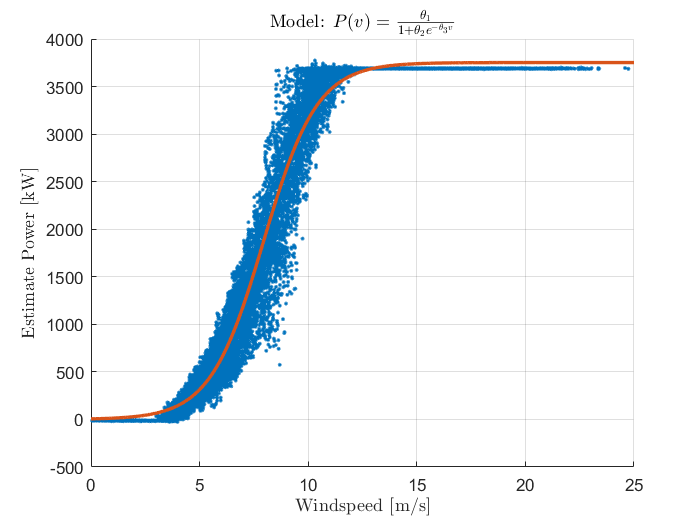

windspeedGrid = [0:0.01:25];
figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, logistic(windspeedGrid, theta), 'LineWidth', 2);
grid on;
title('Model: $P(v) = \frac{\theta_1}{1 + \theta_2 e^{- \theta_3 v}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Estimate Power [kW]', "Interpreter", 'latex');